# Actividad 3 (Evluación)

Alan Iván Flores Juárez | A01736001

%Limpieza de pantalla
clear all
close all
clc

**Robot manipulador**

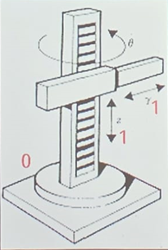

%Declaración de variables simbólicas
syms th1(t) l1 l2(t) l3(t) t

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 1 1];

%Creamos el vector de coordenadas articulares
Q= [th1, l2, l3];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0 ; 0; l1];

Dado que el eje de rotación Th1 inicia alineado con nuestro eje Z1 en nuestro marco de referencia inercial, únicamente se indica la distancia en la posición Z1 de la altura de la base, en nuestro caso L1.

%Matriz de rotación de la junta 2 respecto a 1.... th1 z1

R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];

Y dado que este eje realiza rotaciónes sobre el eje Z1 que a su vez afectará posteriormente la rotación de neustros demás ejes de movimineto dependiendo de Th1, la rotación sobre este eje se indica en una matriz de rotación en Z según sea el ángulo de Th1. (Figúra 1)

%Articulación 2
P(:,:,2)= [l2 ; 0; l3];

Dentro de nuestro nuevo marco de referencia, el movimiento de nuestro segundo eje de movimiento (L2) coincide con el eje X, mienstras que nuestro tercer eje de movimiento (L3) coincide con nuestro eje Z. Por lo que se indica en el vector de posición.

%Matriz de rotación de la junta 2 respecto a 1.... y -90
R(:,:,2)= [0 0 -1;
           0 0 0;
           1 0 0];

Por último se indica la matriz de rotación necesaria para alinear nuestro eje Z con aquel movimineto de nuestro tercer eje L3, por lo que se realiza una rotación en Y de -90 grados. (Figura 3)  Expresadas en le vector de rotación anteriormente mostrado.

%Articulación 3
P(:,:,3)= [0; 0; 0];
%Matriz de rotación de la junta 3 respecto a 2.... th3 z2 
R(:,:,3)= [1 0  0;
           0 1  0;
           0 0  1];


Marco de referencia inercial     Rotación en eje Z               Primera Transformación

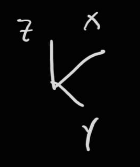            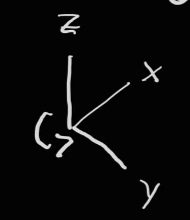       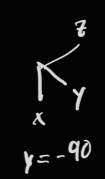 

Figura 1                                   Figura 2                                Figura 3


%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(RO_inv(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/ cos(th1(t)), -sin(th1(t)), 0,  0 \
|                                  |
| sin(th1(t)),  cos(th1(t)), 0,  0 |
|                                  |
|      0,            0,      1, l1 |
|                                  |
\      0,            0,      0,  1 /



Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0,  0 \
|                                  |
| sin(th1(t)),  cos(th1(t)), 0,  0 |
|                                  |
|      0,            0,      1, l1 |
|                                  |
\      0,            0,      0,  1 /



Matriz de Transformación local A2


/ 0, 0, -1, l2(t) \
|                 |
| 0, 0,  0,   0   |
|                 |
| 1, 0,  0, l3(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación global T2


/ 0, 0, -cos(th1(t)), cos(th1(t)) l2(t) \
|                                       |
| 0, 0, -sin(th1(t)), sin(th1(t)) l2(t) |
|                                       |
| 1, 0,       0,          l1 + l3(t)    |
|                                       |
\ 0, 0,       0,              1         /



Matriz de Transformación local A3


/ 1, 0, 0, 0 \
|            |
| 0, 1, 0, 0 |
|            |
| 0, 0, 1, 0 |
|            |
\ 0, 0, 0, 1 /



Matriz de Transformación global T3


/ 0, 0, -cos(th1(t)), cos(th1(t)) l2(t) \
|                                       |
| 0, 0, -sin(th1(t)), sin(th1(t)) l2(t) |
|                                       |
| 1, 0,       0,          l1 + l3(t)    |
|                                       |
\ 0, 0,       0,              1         /




%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ -sin(th1(t)) l2(t), 0, -cos(th1(t)) \
|                                     |
|  cos(th1(t)) l2(t), 0, -sin(th1(t)) |
|                                     |
\          0,         1,       0      /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 1, 0, 0 /





disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   ________               _________                   \
|    d                      d                          |
| - -- l3(t) cos(th1(t)) - -- th1(t) sin(th1(t)) l2(t) |
|   dt                     dt                          |
|                                                      |
|  _________                     ________              |
|   d                             d                    |
|  -- th1(t) cos(th1(t)) l2(t) - -- l3(t) sin(th1(t))  |
|  dt                            dt                    |
|                                                      |
|                       ________                       |
|                        d                             |
|                       -- l2(t)                       |
\                       dt                             /



Según nuestro marco de referencia inercial, el eje de movimiento L2 corresponde con nuestro eje Z, ya que ambos ejes de movimiento, tanto L1, como L2 se encuentran originalmente alineados. De misma manera nuestro eje de movimineto lineal en X y Y  dependen tanto de valores en Th1, L3 y L2. Esto tiene logica basados en nuestro marco de referencia inercial previamente mostrado.

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



De misma manera tiene sentido que el unico eje de movimiento anular sea observado en el eje Z, ya que es el único eje en nuestro marco de referencia inercial que presenta movimiento rotacional, mientras que el eje X y Y no lo hacen.